clc,clear
s=tf('s');

This is your system's open loop transfer function. Replace as per your system design.


$$G\left(s\right)=\frac{1}{\left(2s+1\right)}$$


G= 1/(2*s+1);

Design the K to sarisfy the stready state error requirements and add integrator to ensure zero steady state error. Reduce the gain if compensator is not able to acheive the desired phase margin. In some case a compensator may not be sufficient to achive the desired phase margin, in that case both lead and lag compensator will be required.

K=100;
G=K*G*(1/s);

Find system margins without compensator,

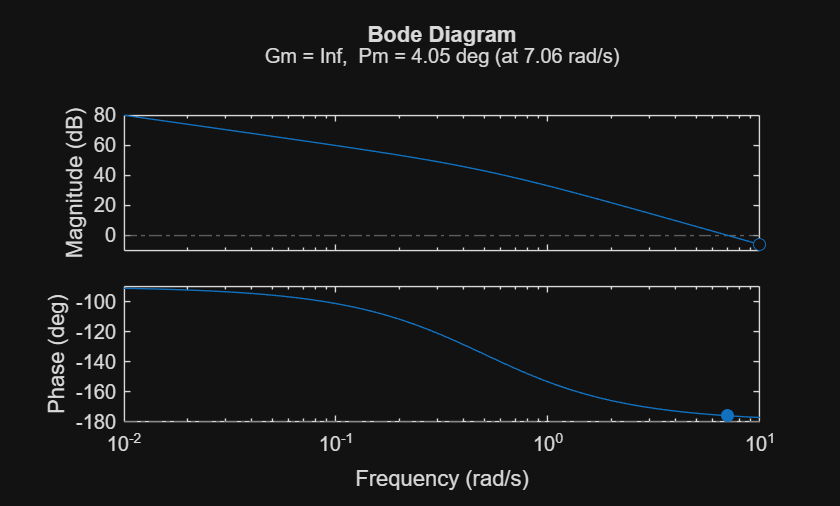

margin(G)

% Display the gain and phase margins
[Gm, Pm, Wpc, Wgc] = margin(G);
fprintf('Gain Margin: %.2f dB at Frequency: %.2f rad/s\n', db(Gm), Wpc);

Gain Margin: Inf dB at Frequency: Inf rad/s


fprintf('Phase Margin: %.2f degrees at Frequency: %.2f rad/s\n', Pm, Wgc);

Phase Margin: 4.05 degrees at Frequency: 7.06 rad/s


i=1;
for phi_d = [30,40,45,50,55,60]
    phi_di(i,:)=phi_d;
    phi_m(i,:)=phi_d-Pm+2;
    alpha(i,:) = (1-sind(phi_m(i,:)))/(1+sind(phi_m(i,:)));

Automatic $\omega_d$calculation

    alpha_attenuation = 10*log10(alpha(i,:));
    [mag,phase,wout] = bode (G,1e-2:0.01:Wgc*10);
    mag_db=mag2db(mag);
    [~,index] = min(abs(mag_db-alpha_attenuation));
    omega = wout(index);

Claculate the compensator time constat to place the additional phase at $\omega_{d\;}$frequency.


$$\tau =\frac{1}{\omega_{d\;} \sqrt{\alpha }}$$


    tau(i,:) = 1/(omega*sqrt(alpha(i,:)));
    
    C= (1+tau(i,:)*s)/(1+alpha(i,:)*tau(i,:)*s);
    figure(1)
    margin(G*C)
    hold on

The frequency response of the Designed Compensator

    figure(2)
    bode(C)
    hold on
    [gm(i,:),pm(i,:)] = margin(G*C);
    fprintf("Gain Margin = %0.2f, and Phase Margin = %0.2f \n",[db(gm(i,:)),pm(i,:)])

Step response of uncompensated closed loop system and compensated closed loop system with the desired phase margins.

    figure(3)
    subplot(2,1,1)
    [y,t]=step(feedback(G*C,1),3);
    plot(t,y)
    hold on
    subplot(2,1,2)
    plot(t,1-y)
    hold on
    i=i+1;
end

Gain Margin = Inf, and Phase Margin = 31.09 
Gain Margin = Inf, and Phase Margin = 40.78 
Gain Margin = Inf, and Phase Margin = 45.62 
Gain Margin = Inf, and Phase Margin = 50.46 
Gain Margin = Inf, and Phase Margin = 55.30 
Gain Margin = Inf, and Phase Margin = 60.12 


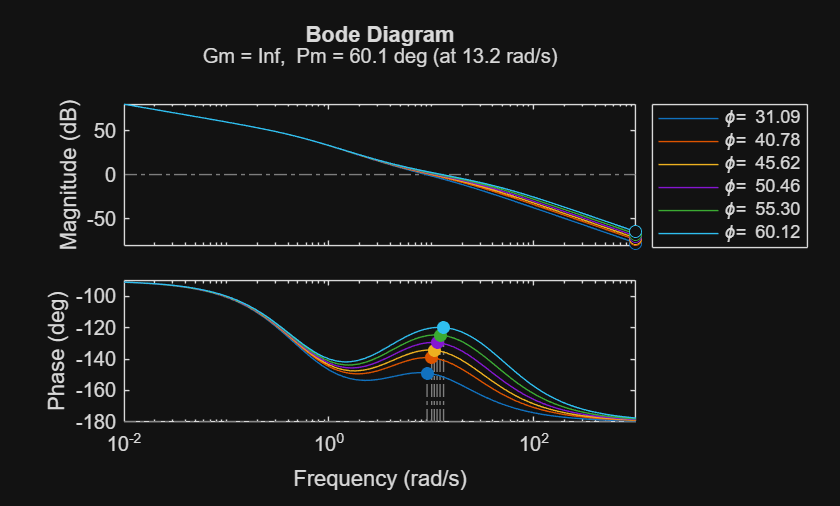

legendLabels = arrayfun(@(x) sprintf('\\phi= %.2f', x), pm, 'UniformOutput', false);
[y,t]=step(feedback(G,1),3);
figure(1),legend(legendLabels,Location="bestoutside");

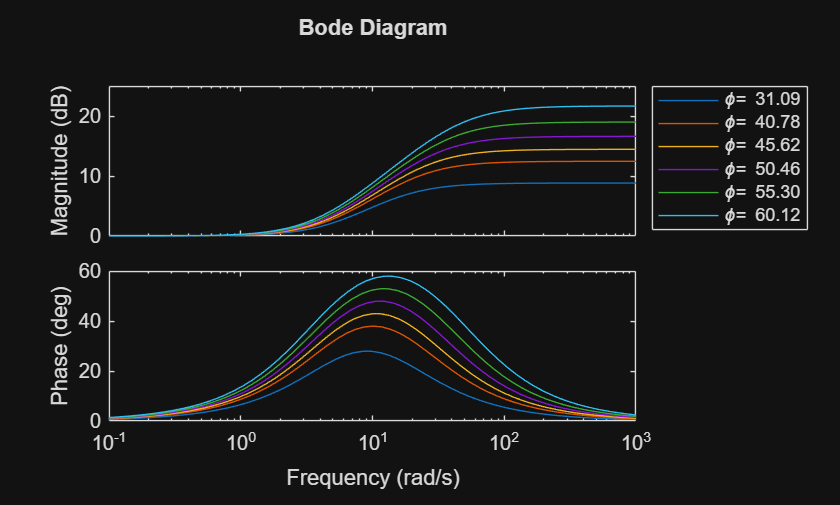


figure(2),legend(legendLabels,Location="bestoutside");

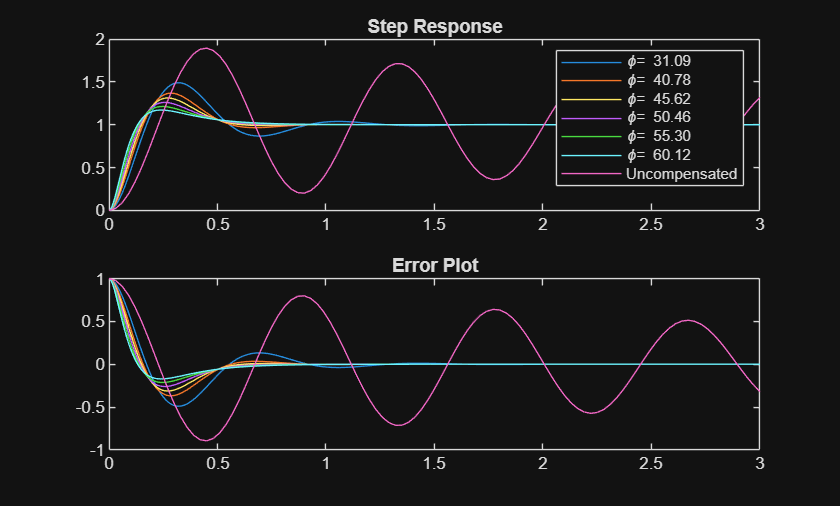

figure(3),subplot(2,1,1), plot(t,y), title("Step Response")
figure(3),subplot(2,1,2), plot(t,1-y),title("Error Plot")
figure(3),subplot(2,1,1)
legendLabels{end+1}='Uncompensated';
legend(legendLabels,Location="northeast")

hold off

PM_uncomensated = ones(size(phi_di))*Pm;
tab=table(phi_di,PM_uncomensated,pm,alpha,tau, ...
    'VariableNames',["PM (Desired)","PM (Actual)", 'PM (Compensated)', "alpha","tau"])

tab = 6×5 table
    PM (Desired)    PM (Actual)    PM (Compensated)     alpha        tau  
    ____________    ___________    ________________    ________    _______

         30           4.0498            31.091          0.36174    0.18251
         40           4.0498             40.78          0.23841    0.20258
         45           4.0498            45.623          0.18951    0.21448
         50           4.0498            50.462          0.14773    0.22822
         55           4.0498            55.295          0.11228    0.24442
         60           4.0498            60.121         0.082493    0.26397


## Save Figures

figList = findall(0, 'Type', 'figure');

for i = 1:length(figList)
  figure(i);
  set(gcf, 'PaperUnits', 'inches');
  set(gcf, 'PaperPosition', [0 0 7 3.5]);
  saveas(gcf, sprintf('figure%d.png', i));
end